# Sistemas realimentados

# Exercícios sobre especificações de sistemas de controle

## 1. Especificações de controle no tempo

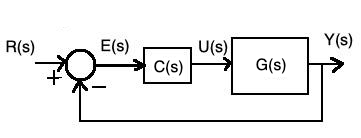

A especificação de controle mais usual é a saída Y seguir a referência R da forma mais próxima possível, para uma referência R na forma de degrau.

Especificações usuais no tempo neste caso são:

- Erro em regime

- Sobreelevação

- Tempo de estabelecimento (ou estabilização)

- Integral absoluta do erro (IAE).

Seja $g(s)=\frac{10}{s^2+6s+5}$ e um controlador $C(s)=K$. Analise cada uma destas especificações quando o ganho K aumenta.

## 1.1 Controlador proporcional K

s=tf('s');
g=10/(s^2+6*s+5)
for C=1:12 % C=K e varia de 1 a 12
    mry=feedback(C*g,1);
    [y,t]=step(mry);
    e=1-y;
    iae(C,1)=trapz(t,abs(e));
    S=stepinfo(y,t);
    up(C,1)=S.Overshoot;
    ts(C,1)=S.SettlingTime;
    erro(C,1)=abs(1-y(end));
end
C=[1:12]';
Tabela1=table(C,up,ts,erro,iae)

1.1 Qual o efeito do ganho Kp=C sobre cada uma destas especificações?

1.2 Dentre as especificações up,ts,erro, qual a que mais afeta o iae?

## 1.2. Controlador PI

Seja agora um controlador PI, $C(s)=K_p+K_I/s=K_p\frac{(s+\frac{K_i}{K_p})}{s}$.

Vamos variar apenas o ganho Kp mantendo fixa a relação $\frac{K_I}{K_p}=2$.

for C=1:12 % C=Kp e varia de 1 a 12 e Ki/Kp se mantêm constante.
    c=tf(C*[1/2 1],[1 0]);
    mry=feedback(c*g,1);
    [y,t]=step(mry);
    e=1-y;
    iae(C,1)=trapz(t,abs(e));
    S=stepinfo(y,t);
    up(C,1)=S.Overshoot;
    ts(C,1)=S.SettlingTime;
    erro(C,1)=abs(1-y(end));
end
C=[1:12]';
Tabela2=table(C,up,ts,erro,iae)

1.2.1 Qual o efeito do ganho Kp sobre cada uma destas especificações?

1.2.2 O que ocorre com o erro em regime agora?

## 1.3 Análise dos sinais para os dois controladores (P e PI)

## Escolha um valor de Kp e compare os sinais y(t),u(t),e(t) para os controladores P e PI.

Kp=1; % Valores de 1 a 12
C=Kp;
mry=feedback(C*g,1);
mru=feedback(C,g);
mre=feedback(1,C*g);
figure;
step(mry,mre,mru);title('Controlador proporcional (P)')

C=tf(Kp*[1/2 1],[1 0]);
mry=feedback(C*g,1);
mru=feedback(C,g);
mre=feedback(1,C*g);
figure;
step(mry,mre,mru);title('Controlador proporcional mais integral (PI)')


1.3.1 Justifique o comportamento destes sinais.

## 2. Efeito do distúrbio na resposta. 

O controlador C(s) deve ser escolhido para que a saída Y siga a entrada R, mas também seja pouco sensível a distúrbios.

Vamos usar o diagrama abaixo e analisar o efeito de um distúrbio em d, na forma de degrau.

Para este exemplo, espera-se que a saída Y dada por $\frac{Y\left(s\right)}{R\left(s\right)}=\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)}$ tenda à entrada R rapidamente.

Espera-se também que o efeito do distúrbio D(s) em Y, dado por $\frac{Y(s)}{D(s)}=\frac{G(s)}{1+C(s)G(s)}$ seja o menor possível. Ou seja, seu efeito em regime deve ser nulo.

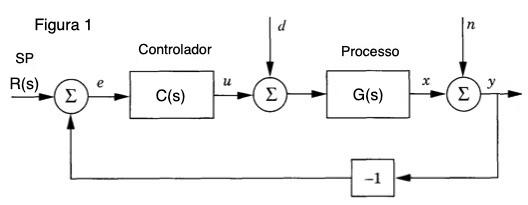

Usaremos os controladores C=Kp e $C(s)=K_p+K_I/s$ para analisar suas capacidades de conseguir um bom desempenho.

Kp=1; % variar Kp (1 a 12) e observar o efeito
C1=Kp;
C2=tf(Kp*[1/2 1],[1 0]);
mry1=feedback(C1*g,1);
mdy1=feedback(g,C1);
mry2=feedback(C2*g,1);
mdy2=feedback(g,C2);
figure;step(mry1,mry2);legend('P','PI');title('Resposta ao degrau para os dois controladores');
figure;step(mdy1,mdy2);legend('P','PI');title('Resposta ao distúrbio para os dois controladores');



## 2.1 Análise para múltiplos valores de ganho


for C=1:12 % C=K e varia de 1 a 12
    mry=feedback(C*g,1);
    mdy=feedback(g,C);
    [y,t]=step(mry,5);
    e=1-y;
    iaekr(C,1)=trapz(t,abs(e));
    [y,t]=step(mdy,5);
    e=0-y;
    iaekd(C,1)=trapz(t,abs(e));
end

for C=1:12 % Kp e varia de 1 a 12 e o zero é fixo.
    c=tf(C*[1/2 1],[1 0]);
    mry=feedback(c*g,1);
    mdy=feedback(g,c);
    [y,t]=step(mry,5);
    e=1-y;
    iaepir(C,1)=trapz(t,abs(e));
    [y,t]=step(mdy,5);
    e=0-y;
    iaepid(C,1)=trapz(t,abs(e));
end

C=[1:12]';
Tabela2=table(C,iaekr,iaepir,iaekd,iaepid)
figure;
subplot(211);bar([iaekr iaepir]);title('IAE devido ao degrau em R');legend('P','PI')
subplot(212);bar([iaekd iaepid]);title('IAE devido ao distúrbio');legend('P','PI')


2.1.1Como escolher o controlador e o ganho para conseguir um bom desempenho em termos de seguir referência e rejeitar o distúrbio?

## 3. Modelos de referência.

Uma forma de especificar um sistema de controle é escolher a função de transferência cuja resposta tenha as características desejadas em malha fechada. 

**Exemplo1** : Modelo de referência m(s) com erro nulo à entrada degrau, sobreelevação nula, e tempo de estabelecimento de 50 segundos.

m=tf(1,[10 1]);
figure;step(m);

**Exemplo2** : Modelo de referência m(s)  com erro nulo à entrada degrau, sobreelevação de 5%, e tempo de estabelecimento de 10 segundos.

up=5;
ts=10;
a=log(up/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(ts*zeta);
m=wn^2/(s^2+2*zeta*wn*s+wn^2)
figure;step(m);
stepinfo(m)


## 3.1 Seja um sistema cujo modelo é dado por $g(s)=\frac{1}{(s+1)^4}$.

Sugira um modelo de referência de ordem 1 para especificar a resposta desejada para este sistema em malha fechada, e compare sua resposta com a deste modelo.

g=1/(s+1)^4
figure;
step(g)

**Exemplo:**

gr=tf(1,[4 1]); % Escolhadiferentes modelos aqui
figure;step(g,gr);

## 3.2 Especifique agora um modelo de referência de ordem 2 que dê uma resposta desejada para o sistema dado por $g(s)=\frac{1}{s^2+0.16s+0.16}$

g=tf(1,[1 0.16 0.16]);
figure;step(g);

## 3.3 Adicione um terceiro polo ao sistema especificado no item 3.2, mantendo a mesma sobreelevação e tempo de estabelecimento.

Plote a resposta ao degrau do sistema de ordem 2 e ordem 3, comparando.

## 4. Relação do IAE com UP e tempos de resposta.

Analisaremos agora a relação da íntegra absoluta do erro (IAE) com a sobreelevação, o tempo de estabelecimento e o tempo de subida.

Para isto, usaremos a FT de malha aberta $g(s)=\frac{K}{s(s+5)}$, avaliando o efeito do aumento do ganho K em malha fechada.

Observe as figuras geradas e tire suas conclusões sobre a relação do IAE com as demais especificações.

k=linspace(5,60,20);
iae=[];
up=[];
ts=[];
for i=1:20
    g=k(i)/(s*(s+5));
    m=feedback(g,1);
    [y,t]=step(m,5);
    S=stepinfo(y,t);
    e=1-y;
    iae(i,1)=trapz(t,abs(e));
    up(i,1)=S.Overshoot;
    ts(i,1)=S.SettlingTime;
    tr(i,1)=S.RiseTime;
end
figure;
subplot(4,1,1);bar(k,iae);title('IAE');
subplot(4,1,2);bar(k,up);title('UP');
subplot(4,1,3);bar(k,ts);title('Settling Time')
subplot(4,1,4);bar(k,tr);title('Rise Time');
xlabel('Valores do ganho K');


Veja também:

figure;
subplot(3,1,1);scatter(iae,up);
subplot(3,1,2);scatter(iae,ts);
subplot(3,1,3);scatter(iae,tr);